clear all
% Generate random signal
AL_ref = [2,0,2,0,0,9,3,3,4]; % Andrew's student number
FC_ref = [2,0,2,0,3,2,1,1,7]; % Frank's student number
x1 = repmat(AL_ref,1,100) 

x1 =      2     0     2     0     0     9     3     3     4     2     0     2     0     0     9     3     3     4     2     0     2     0     0     9     3     3     4     2     0     2     0     0     9     3     3     4     2     0     2     0     0     9     3     3     4     2     0     2     0     0


x1 = x1 - repmat(mean(x1),1,900)

x1 =    -0.5556   -2.5556   -0.5556   -2.5556   -2.5556    6.4444    0.4444    0.4444    1.4444   -0.5556   -2.5556   -0.5556   -2.5556   -2.5556    6.4444    0.4444    0.4444    1.4444   -0.5556   -2.5556   -0.5556   -2.5556   -2.5556    6.4444    0.4444    0.4444    1.4444   -0.5556   -2.5556   -0.5556   -2.5556   -2.5556    6.4444    0.4444    0.4444    1.4444   -0.5556   -2.5556   -0.5556   -2.5556   -2.5556    6.4444    0.4444    0.4444    1.4444   -0.5556   -2.5556   -0.5556   -2.5556   -2.5556


x2 = repmat(FC_ref,1,100) 

x2 =      2     0     2     0     3     2     1     1     7     2     0     2     0     3     2     1     1     7     2     0     2     0     3     2     1     1     7     2     0     2     0     3     2     1     1     7     2     0     2     0     3     2     1     1     7     2     0     2     0     3


x2 = x2 - repmat(mean(x2),1,900)

x2 =      0    -2     0    -2     1     0    -1    -1     5     0    -2     0    -2     1     0    -1    -1     5     0    -2     0    -2     1     0    -1    -1     5     0    -2     0    -2     1     0    -1    -1     5     0    -2     0    -2     1     0    -1    -1     5     0    -2     0    -2     1


fs = round((9334+2117)/2)

fs = 5726

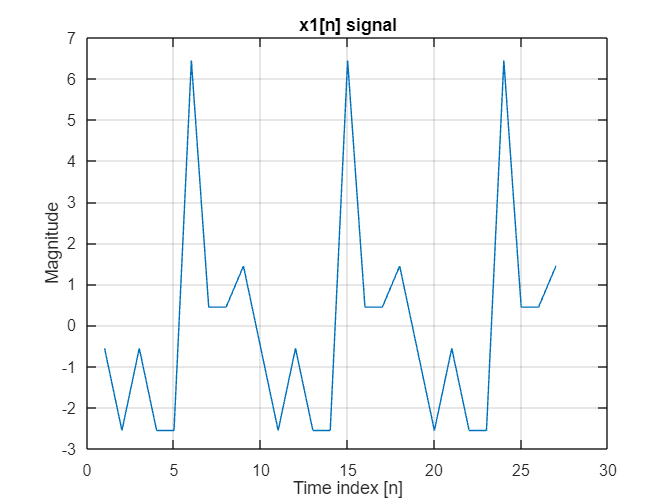



% Plot time signals
figure;
plot(1:27,x1(1:27));
title('x1[n] signal')
xlabel('Time index [n]');
ylabel('Magnitude');
grid on;

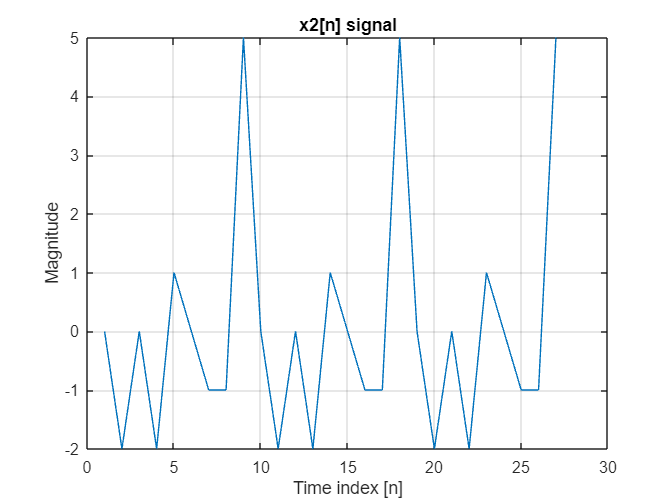

figure;
plot(1:27,x2(1:27));
title('x2[n] signal')
xlabel('n');
ylabel('Magnitude');
xlabel('Time index [n]');
grid on;

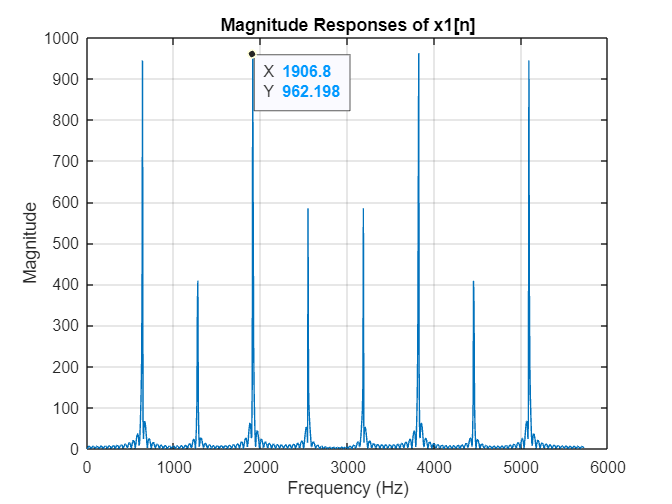


% Find magnitude reponse
N_FFT = 1024; % FFT size
X1 = fft(x1,N_FFT);
X2 = fft(x2,N_FFT);
f_axis = (0:N_FFT-1)*fs/N_FFT; % Frequency axis

% Plot magnitude 
figure;
plot(f_axis,abs(X1));
title('Magnitude Responses of x1[n]');
xlabel('Frequency (Hz)');
ylabel('Magnitude');
grid on;

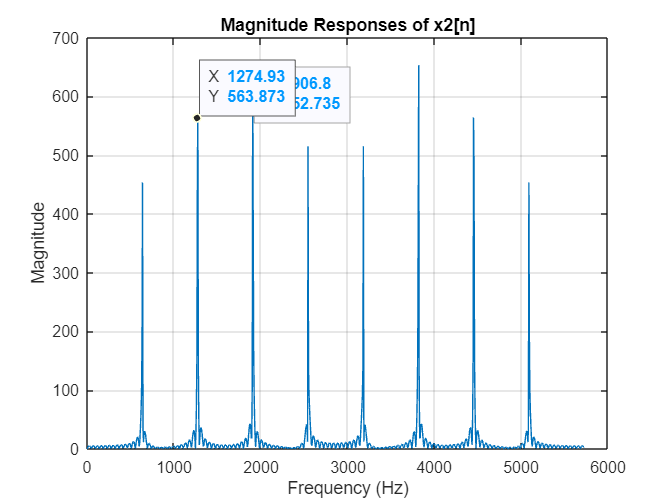

figure;
plot(f_axis,abs(X2));
title('Magnitude Responses of x2[n]');
xlabel('Frequency (Hz)');
ylabel('Magnitude');
grid on;

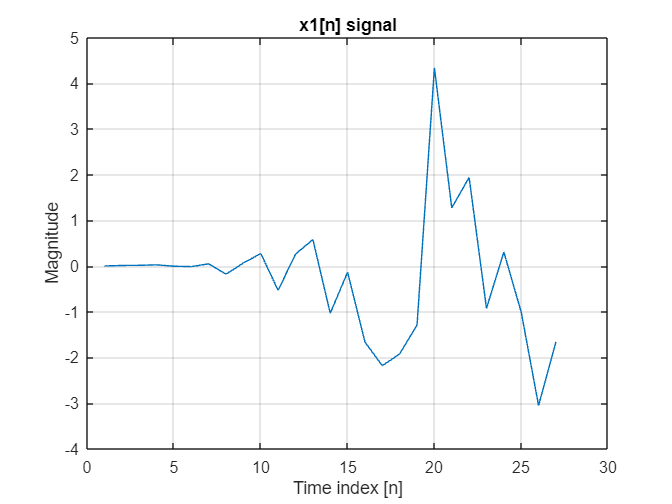

filt_x1 = filter(Num1, 1,x1);
filt_x2 = filter(Num2, 1,x2);

% Plot time signals
figure;
plot(1:27,filt_x1(1:27));
title('x1[n] signal')
xlabel('Time index [n]');
ylabel('Magnitude');
grid on;

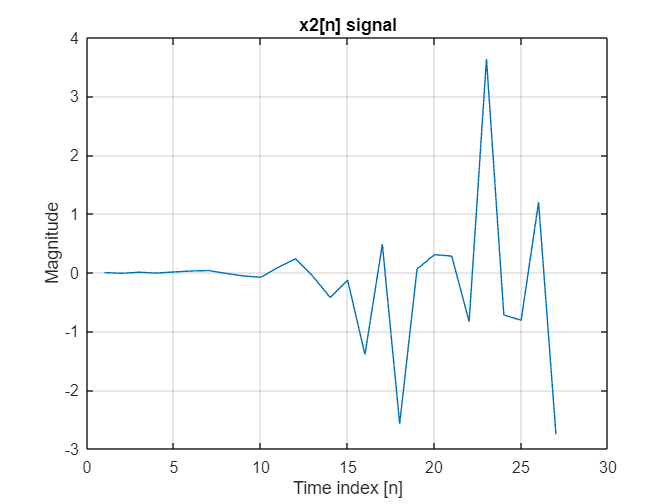

figure;
plot(1:27,filt_x2(1:27));
title('x2[n] signal')
xlabel('Time index [n]');
ylabel('Magnitude');
grid on;

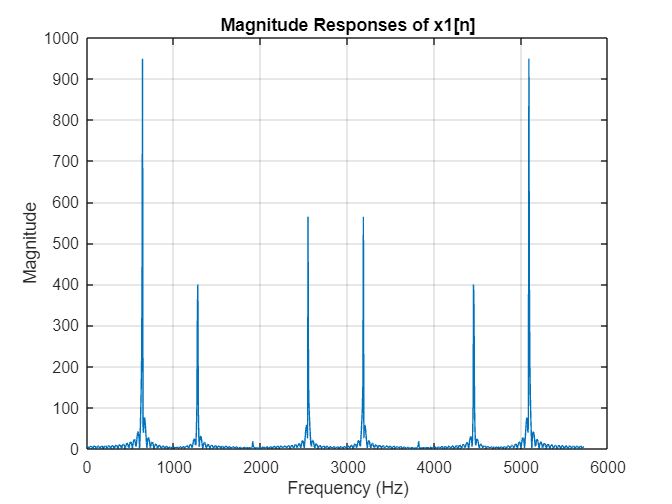


% Find magnitude reponse
N_FFT = 1024; % FFT size
X1 = fft(filt_x1,N_FFT);
X2 = fft(filt_x2,N_FFT);
f_axis = (0:N_FFT-1)*fs/N_FFT; % Frequency axis

% Plot magnitude 
figure;
plot(f_axis,abs(X1));
title('Magnitude Responses of x1[n]');
xlabel('Frequency (Hz)');
ylabel('Magnitude');
grid on;

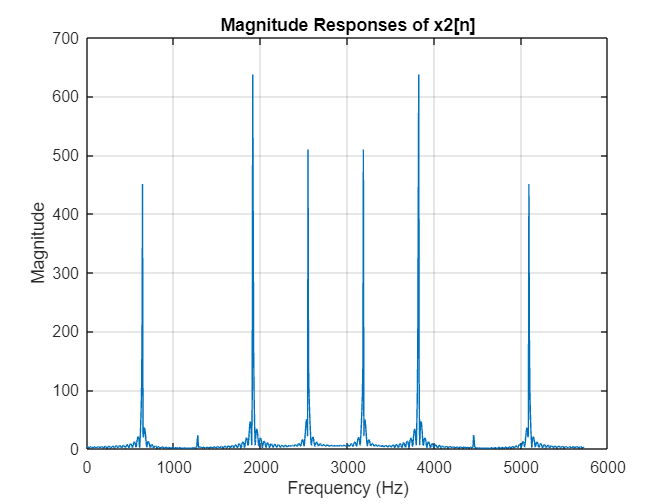

figure;
plot(f_axis,abs(X2));
title('Magnitude Responses of x2[n]');
xlabel('Frequency (Hz)');
ylabel('Magnitude');
grid on;

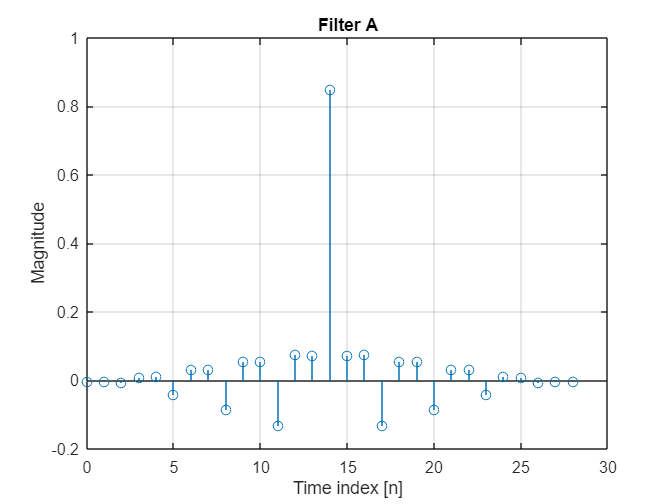

filter_a = single(Num1);
filter_b = single(Num2); 

%save("AssData.mat")

% <<<<---- Added extra plots in this section for report ---->>>>
% Plot time domain
figure;
stem(0:length(filter_a)-1,filter_a);
title('Filter A');
xlabel('Time index [n]');
ylabel('Magnitude');
grid on;

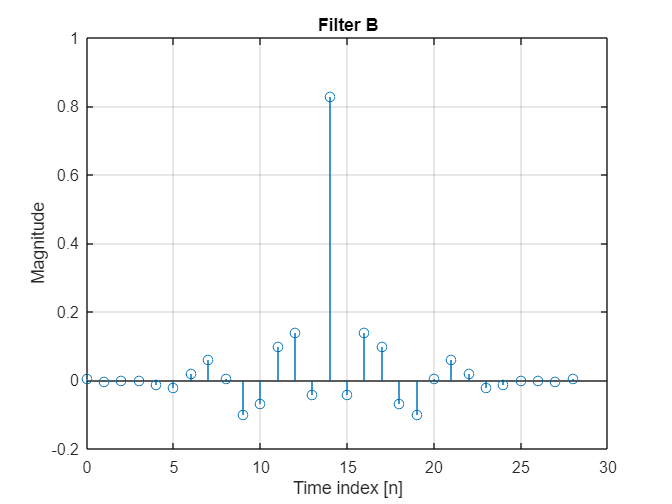


figure;
stem(0:length(filter_b)-1,filter_b);
title('Filter B');
xlabel('Time index [n]');
ylabel('Magnitude');
grid on;

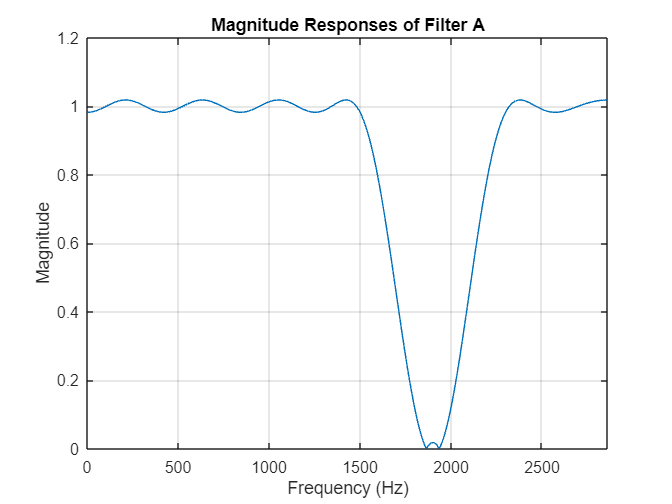



% Find magnitude reponse
N_FFT = 1024; % FFT size
Filter_A = fft(filter_a,N_FFT);
Filter_B = fft(filter_b,N_FFT);
f_axis = (0:N_FFT-1)*fs/N_FFT; % Frequency axis

% Plot magnitude 
figure;
plot(f_axis(1:(N_FFT/2)),abs(Filter_A(1:(N_FFT/2))));
title('Magnitude Responses of Filter A');
xlabel('Frequency (Hz)');
ylabel('Magnitude');
grid on;
xlim([0 (fs/2)]);

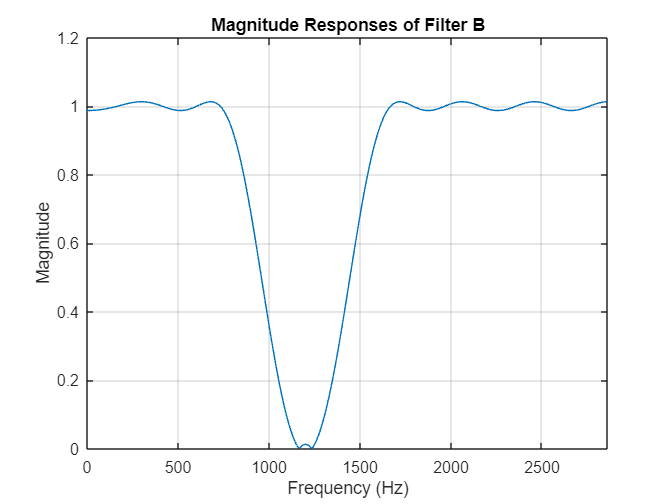

figure;
plot(f_axis(1:(N_FFT/2)),abs(Filter_B(1:(N_FFT/2))));
title('Magnitude Responses of Filter B');
xlabel('Frequency (Hz)');
ylabel('Magnitude');
xlim([0 (fs/2)]);
grid on;

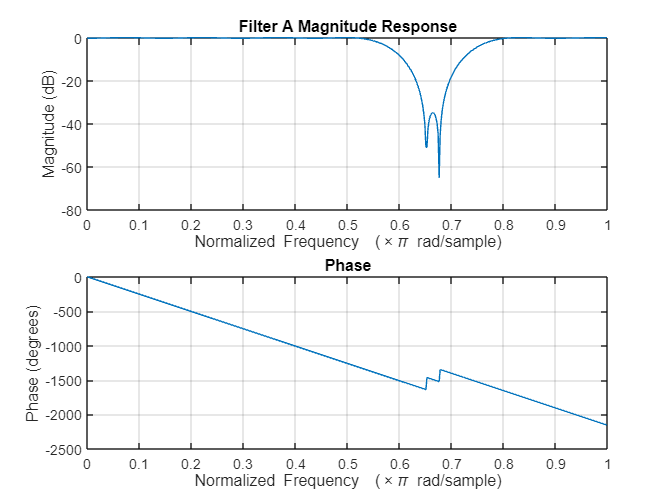


% [H, w] = freqz(filter_a,1,N_FFT); % Compute frequency response
% figure;
% plot(w/pi, abs(H)); % Normalised frequency reponse
% xlabel('Normalised Frequency (\times\pi rad/ample)');
% ylabel('Magnitude');
% title('Magnitude Response of Filter A');
% grid on;
% 
% [phi, w] = phasez(filter_a,1,N_FFT); % Compute phase response
% figure;
% plot(w/phi, unwrap(phi)); % Unwrap to avoid discontinuities
% xlabel('Normalised Frequency (\times\pi rad/ample)');
% ylabel('Phase (radians)');
% title('Phase Response of Filter A');
% grid on;

freqz(filter_a,1);
title('Filter A Magnitude Response');

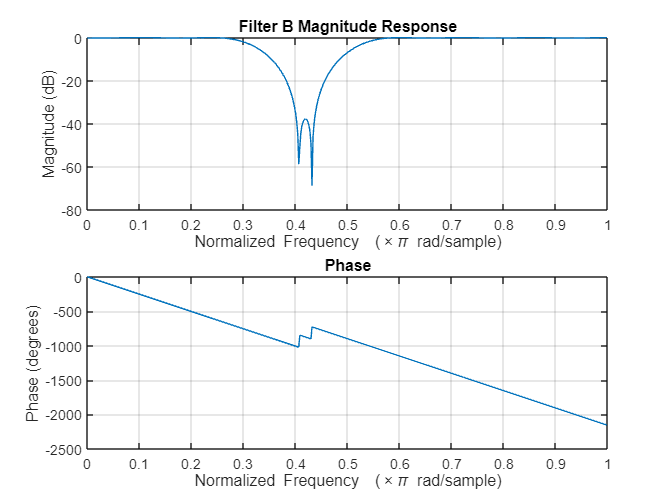

freqz(filter_b,1);
title('Filter B Magnitude Response');

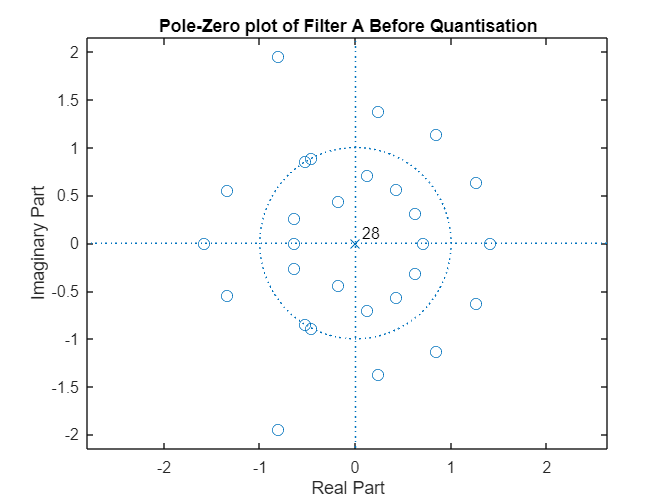


figure;
zplane(filter_a);
title('Pole-Zero plot of Filter A Before Quantisation');

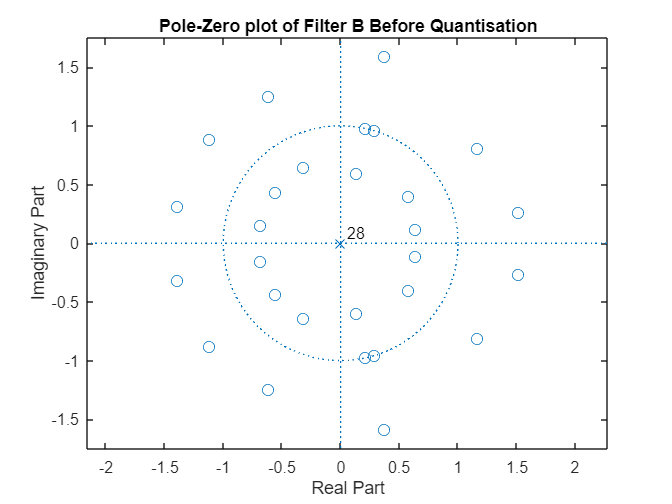

figure;
zplane(filter_b);
title('Pole-Zero plot of Filter B Before Quantisation');

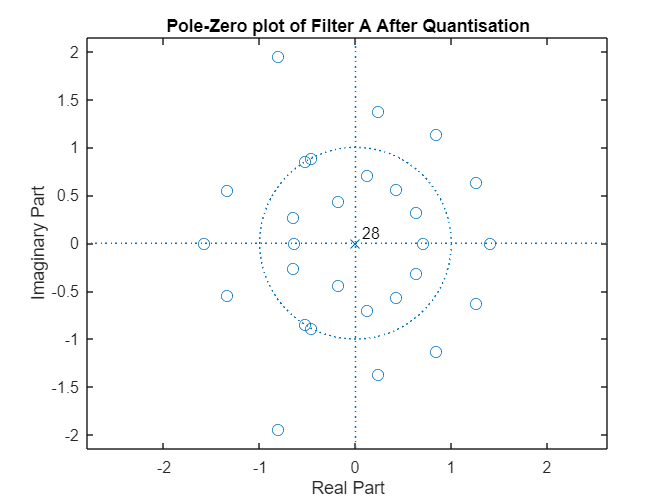


q = quantizer([16 15]); % Assuming 16 integer bits, 15 fractional bits
filter_a_q = quantize(q, filter_a);
filter_b_q = quantize(q, filter_b);
H_a_q = dfilt.df2t(filter_a_q,1); % Direct Form II Transposed
H_b_q = dfilt.df2t(filter_b_q,1); % Direct Form II Transposed

figure;
zplane(filter_a_q);
title('Pole-Zero plot of Filter A After Quantisation');

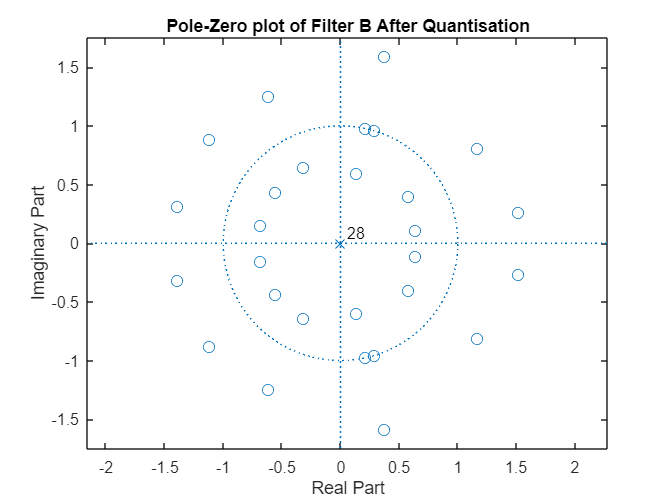

figure;
zplane(filter_b_q);
title('Pole-Zero plot of Filter B After Quantisation');

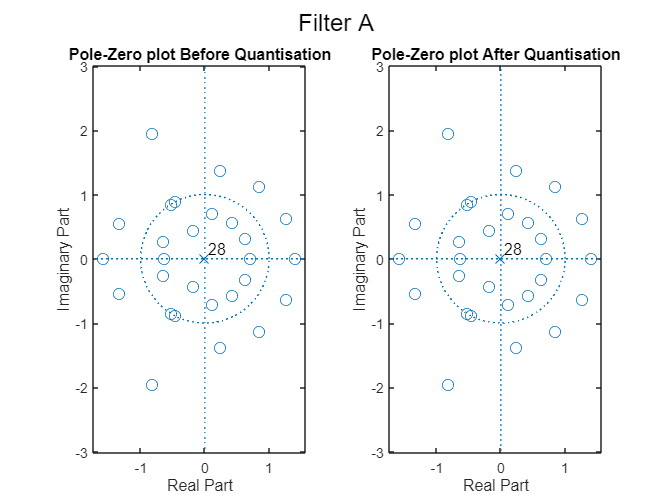


figure;
subplot(1,2,1);
zplane(filter_a);
title('Pole-Zero plot Before Quantisation');
subplot(1,2,2);
zplane(filter_a_q);
title('Pole-Zero plot After Quantisation');
sgtitle('Filter A');

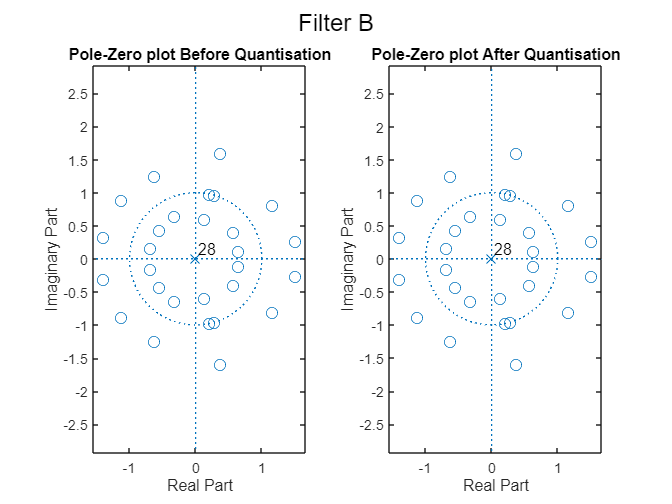


figure;
subplot(1,2,1);
zplane(filter_b);
title('Pole-Zero plot Before Quantisation');
subplot(1,2,2);
zplane(filter_b_q);
title('Pole-Zero plot After Quantisation');
sgtitle('Filter B');

% figure;
% zplane(H_a_q.numerator,1);
% OR JUST FVTOLL THE WHOLE FUCKING THING!
fvtool(filter_a,1)

FC_filtered = conv(filter_b,x2,"full")'

FC_filtered = 928×1 single column vector
         0
   -0.0123
    0.0057
   -0.0087
    0.0105
    0.0273
    0.0344
   -0.0138
   -0.0572
   -0.0806


AL_filtered = conv(filter_a,x1,"full")'

AL_filtered = 928×1 single column vector
    0.0023
    0.0126
    0.0160
    0.0265
   -0.0040
   -0.0125
    0.0496
   -0.1781
    0.0677
    0.2732


% <<<<---- Added extra plots in this section for report ---->>>>
x2_filtered = conv(filter_b,x2,"full")'

x2_filtered = 928×1 single column vector
         0
   -0.0123
    0.0057
   -0.0087
    0.0105
    0.0273
    0.0344
   -0.0138
   -0.0572
   -0.0806


x1_filtered = conv(filter_a,x1,"full")'

x1_filtered = 928×1 single column vector
    0.0023
    0.0126
    0.0160
    0.0265
   -0.0040
   -0.0125
    0.0496
   -0.1781
    0.0677
    0.2732


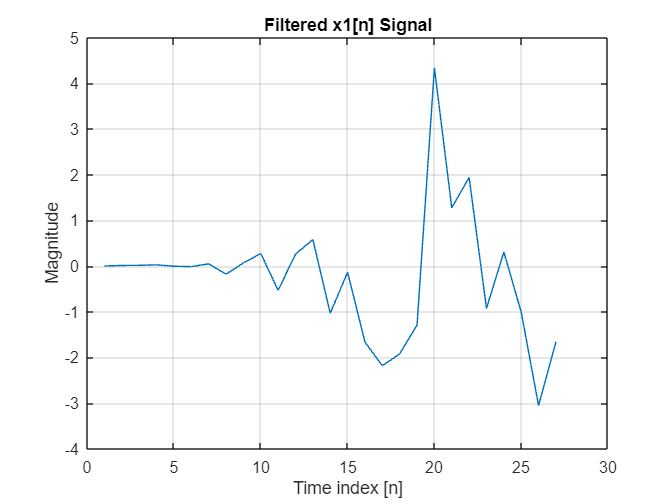


% Plot time signals
figure;
plot(1:27,x1_filtered(1:27));
title('Filtered x1[n] Signal')
xlabel('Time index [n]');
ylabel('Magnitude');
grid on;

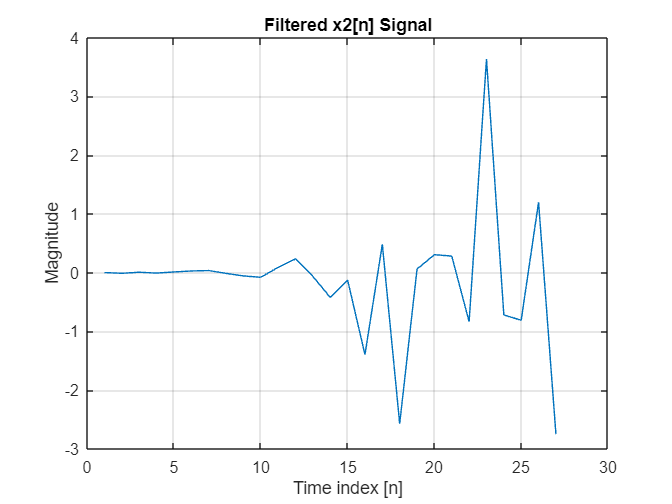

figure;
plot(1:27,x2_filtered(1:27));
title('Filtered x2[n] Signal')
xlabel('Time index [n]');
ylabel('Magnitude');
grid on;

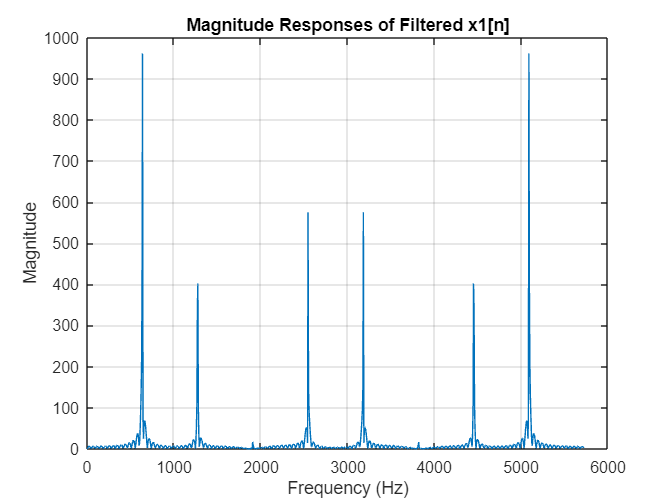


% Find magnitude reponse
N_FFT = 1024; % FFT size
X1_filtered = fft(x1_filtered,N_FFT);
X2_filtered = fft(x2_filtered,N_FFT);
f_axis = (0:N_FFT-1)*fs/N_FFT; % Frequency axis

% Plot magnitude     
figure;
plot(f_axis,abs(X1_filtered));
title('Magnitude Responses of Filtered x1[n]');
xlabel('Frequency (Hz)');
ylabel('Magnitude');
grid on;

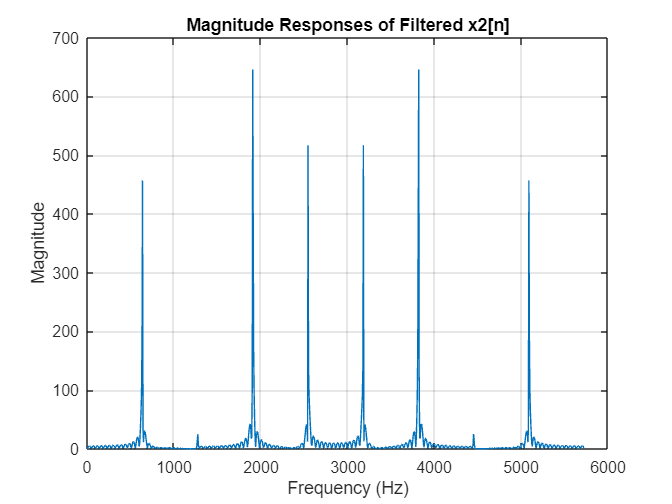

figure;
plot(f_axis,abs(X2_filtered));
title('Magnitude Responses of Filtered x2[n]');
xlabel('Frequency (Hz)');
ylabel('Magnitude');
grid on;

AL_ccs = readmatrix("Clion/cmake-build-debug/filter_AL.txt")
FC_ccs = readmatrix("Clion/cmake-build-debug/filter_FC.txt")

diff_FC = 10*log10(sum((FC_ccs-FC_filtered).^2))
diff_AL = 10*log10(sum((AL_ccs-AL_filtered).^2))